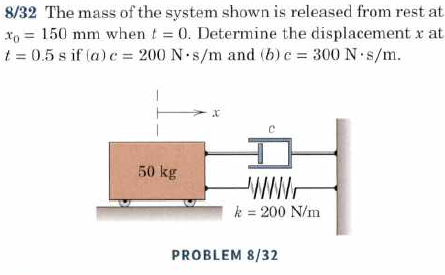

x0 = 0.150

x0 = 0.1500

t0 = 0

t0 = 0


k = 200

k = 200

m = 50

m = 50


c = [200 300]

c =    200   300



w_n = sqrt(k/m)

w_n = 2

eta = c/(2*m*w_n)

eta =     1.0000    1.5000



%for overdæmpet
gamma_1 = w_n*(-eta(2) + sqrt(eta(2)^2 - 1))

gamma_1 = -0.7639

gamma_2 = w_n*(-eta(2) - sqrt(eta(2)^2 - 1))

gamma_2 = -5.2361


syms A1 A2 t x

x(t) = A1 * exp(gamma_1 * t) + A2 * exp(gamma_2 * t)

$$x(t) = A_{2}\,{\mathrm{e}}^{-\frac{1473822112022165\,t}{281474976710656}}+A_{1}\,{\mathrm{e}}^{-\frac{215027748241771\,t}{281474976710656}}$$

v(t) = diff(x(t), t)

$$v(t) = -\frac{1473822112022165\,A_{2}\,{\mathrm{e}}^{-\frac{1473822112022165\,t}{281474976710656}}}{281474976710656}-\frac{215027748241771\,A_{1}\,{\mathrm{e}}^{-\frac{215027748241771\,t}{281474976710656}}}{281474976710656}$$


[A1 A2] = solve([x(0) == 0.150, v(0)==0], [A1, A2])

$$A1 = \frac{884293267213299}{5035177455121576}$$

$$A2 = -\frac{645083244725313}{25175887275607880}$$


x_r(t) = A1 * exp(gamma_1 * t) + A2 * exp(gamma_2 * t)

$$x\_r(t) = \frac{884293267213299\,{\mathrm{e}}^{-\frac{215027748241771\,t}{281474976710656}}}{5035177455121576}-\frac{645083244725313\,{\mathrm{e}}^{-\frac{1473822112022165\,t}{281474976710656}}}{25175887275607880}$$

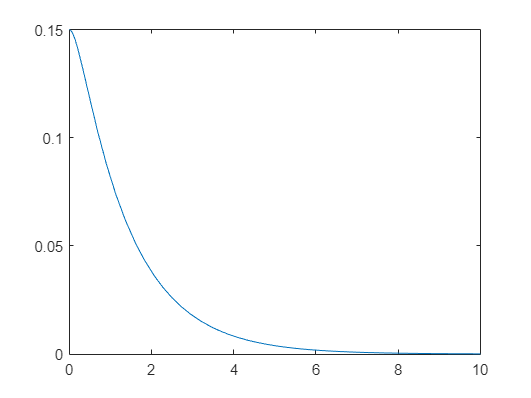


fplot(x_r(t))
xlim([0 10])


vpa(x_r(0.5))

$$ans = 0.11799683989550525363083517269092$$


%for kritisk dæmpet

syms A1 A2 t x A1_k A2_k

x_k(t) = (A1_k + A2_k * t)*exp(-w_n * t)

$$x\_k(t) = {\mathrm{e}}^{-2\,t}\,\left(A_{1,k}+A_{2,k}\,t\right)$$

v_k(t) = diff(x_k(t), t)

$$v\_k(t) = A_{2,k}\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-2\,t}\,\left(A_{1,k}+A_{2,k}\,t\right)$$


[A1_k A2_k] = solve([x_k(0) == 0.150, v_k(0) == 0], [A1_k A2_k])

$$A1\_k = \frac{3}{20}$$

$$A2\_k = \frac{3}{10}$$


x_k_r(t) = (A1_k + A2_k * t)*exp(-w_n * t)

$$x\_k\_r(t) = {\mathrm{e}}^{-2\,t}\,\left(\frac{3\,t}{10}+\frac{3}{20}\right)$$

vpa(x_k_r(0.5))

$$ans = 0.11036383235143269647865713104844$$

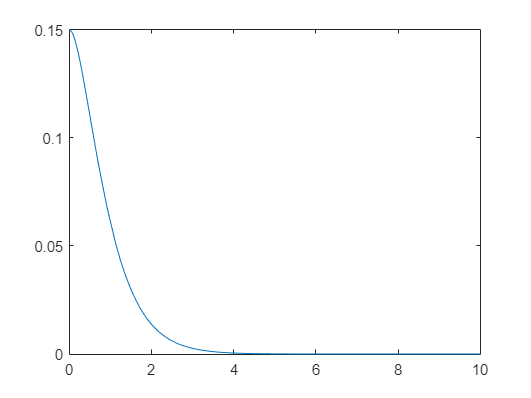


fplot(x_k_r(t))
xlim([0 10])